Problem 1

A)

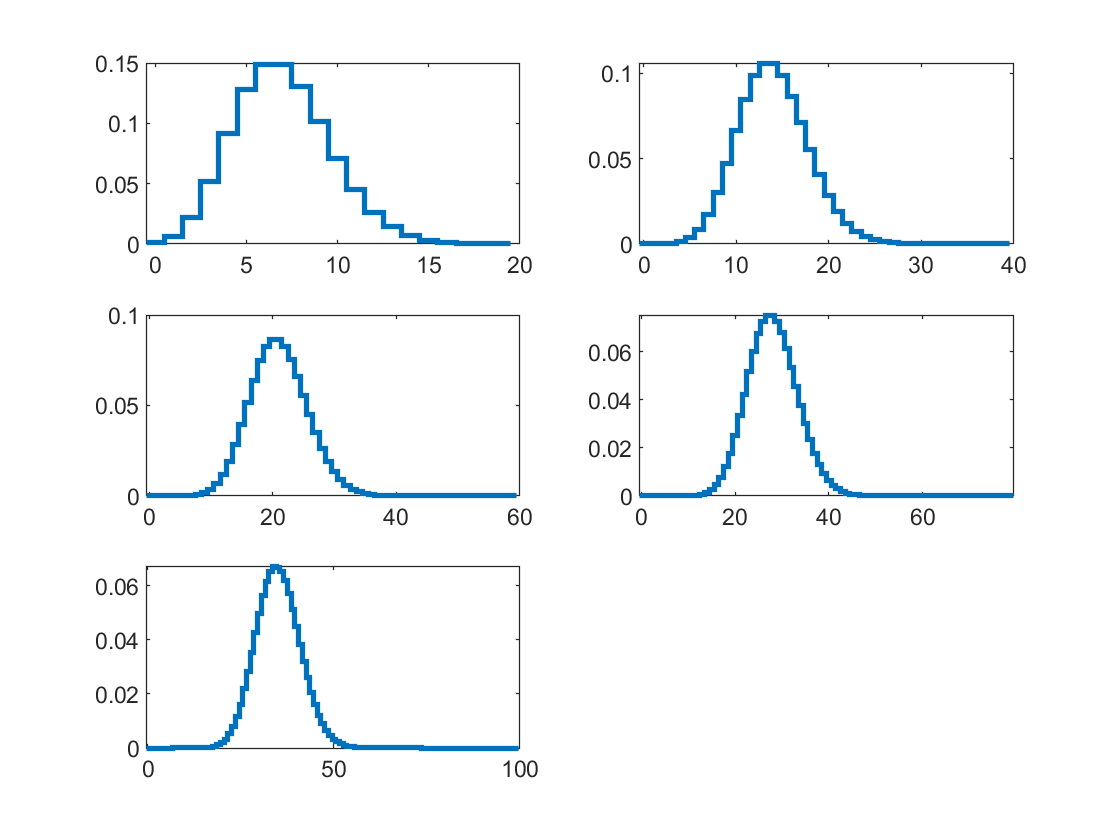

cosmic = makedist("Poisson",'lambda',7);
gamma = makedist("Poisson",'lambda',15);
x = 0:20;
u = pdf(cosmic,x);
v = u;
subplot(3,2,1)
stairs(x-0.5,u,"LineWidth",2)
for i = 1:4
    dayx = conv(u,v);
    x = 0:20*(i+1);
    subplot(3,2,i+1)
    stairs(x-0.5,dayx,"LineWidth",2)
    u = dayx;
end

B)

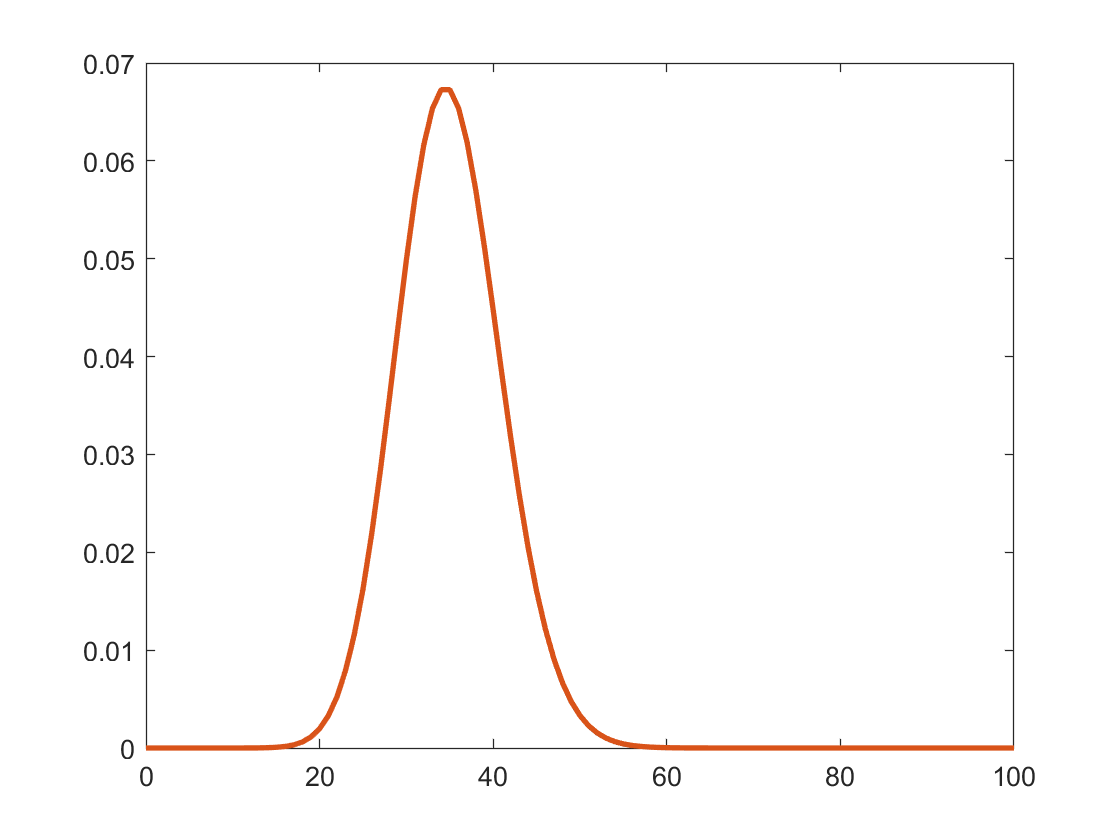

poissontest = makedist("Poisson", 'lambda',7*5);
ytest = pdf(poissontest,x);
subplot(1,1,1)
plot(x,u,x,ytest,"LineWidth",2)

sum(ytest-u)

ans = 7.2475e-05

Because the sum of the difference between the Poisson distribution after 5 days and the test Poisson distribution with 7 * 5 as the mean value is so small with e-05, they are basically the same. Therefore the summed probability distribution is still a Poisson distribution.

C)

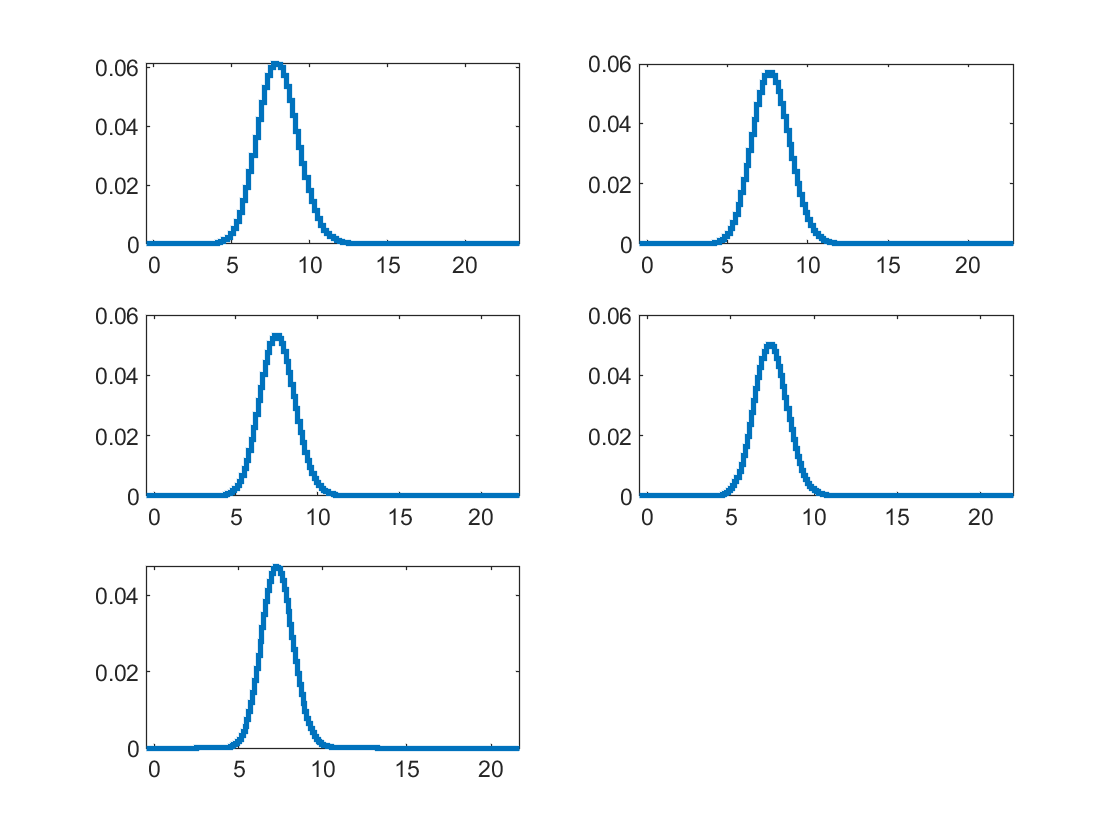

for i = 5:9
    dayx = conv(u,v);
    x = 0:20*(i+1);
    subplot(3,2,i-4)
    stairs(x/i-0.5,dayx,"LineWidth",2)
    u = dayx;
end

It becomes much more like a Gaussian Distribution as the number of days becomes larger. 